syms t w1 w2;
f(t,w1,w2) = [w1*(4-0.0003*w1-0.0004*w2), w2*(2-0.0002*w1-0.0001*w2)];

h = 0.01;

[t_values, w1_values, w2_values] = RK4(h, f);
fprintf('----------------------------------------------------\n');

----------------------------------------------------


fprintf('RK4 method with h=%f:\n', h);

RK4 method with h=0.010000:


fprintf(['Since there are too many values, ' ...
    'just print values with interval length 1/10, i.e., ' ...
    'only print it once every 10 times\n']);

Since there are too many values, just print values with interval length 1/10, i.e., only print it once every 10 times


fprintf('Approximated w1 values are:\n');

Approximated w1 values are:


disp(w1_values(1:10:end));

   1.0e+04 *

    1.0000    0.7804    0.6527    0.5675    0.5049    0.4553    0.4134    0.3764    0.3425    0.3106    0.2802    0.2509    0.2227    0.1956    0.1698    0.1454    0.1228    0.1021    0.0836    0.0673    0.0532    0.0414    0.0317    0.0239    0.0178    0.0130    0.0094    0.0068    0.0048    0.0034    0.0023    0.0016    0.0011    0.0008    0.0005    0.0004    0.0002    0.0002    0.0001    0.0001    0.0001



fprintf('Approximated w2 values are:\n');

Approximated w2 values are:


disp(w2_values(1:10:end));

   1.0e+04 *

    1.0000    0.9307    0.8999    0.8901    0.8936    0.9064    0.9263    0.9518    0.9823    1.0171    1.0557    1.0980    1.1435    1.1919    1.2427    1.2955    1.3497    1.4045    1.4593    1.5133    1.5657    1.6157    1.6629    1.7066    1.7466    1.7827    1.8148    1.8431    1.8677    1.8890    1.9072    1.9227    1.9358    1.9468    1.9560    1.9637    1.9701    1.9754    1.9797    1.9833    1.9863



fprintf('----------------------------------------------------\n');

----------------------------------------------------


k = 30;
fprintf(['To see the convergence of w1 and w2 values clearly, ' ...
    'print last %d values\n'], k);

To see the convergence of w1 and w2 values clearly, print last 30 values


fprintf('Last %d approximated w1 values are:\n', k);

Last 30 approximated w1 values are:


disp(w1_values(end-k+1:end));

    1.5846    1.5239    1.4655    1.4093    1.3553    1.3033    1.2533    1.2052    1.1589    1.1143    1.0715    1.0303    0.9907    0.9525    0.9159    0.8806    0.8467    0.8140    0.7826    0.7525    0.7234    0.6955    0.6687    0.6428    0.6180    0.5941    0.5712    0.5491    0.5279    0.5074



fprintf('Last %d approximated w2 values are:\n', k);

Last 30 approximated w2 values are:


disp(w2_values(end-k+1:end));

   1.0e+04 *

    1.9758    1.9763    1.9768    1.9772    1.9776    1.9781    1.9785    1.9789    1.9793    1.9797    1.9801    1.9805    1.9809    1.9813    1.9816    1.9820    1.9823    1.9827    1.9830    1.9833    1.9837    1.9840    1.9843    1.9846    1.9849    1.9852    1.9855    1.9858    1.9860    1.9863



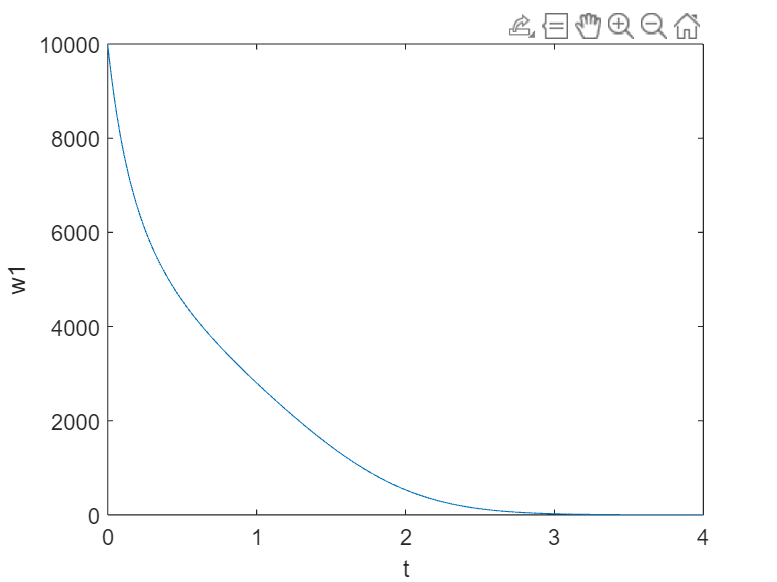


f1 = figure('Name','x-w1 graph');
plot(t_values, w1_values);
xlabel('t');
ylabel('w1');

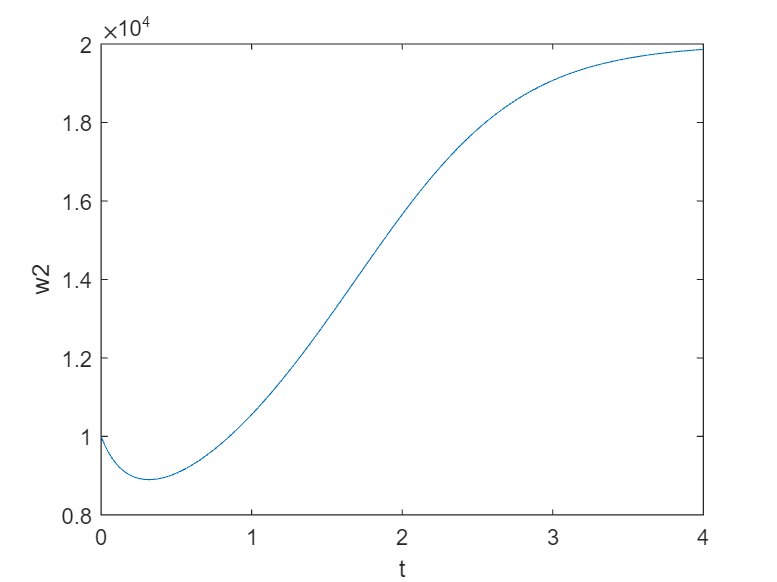

f2 = figure('Name','x-w2 graph');
plot(t_values, w2_values);
xlabel('t');
ylabel('w2');

function [t_values, w1_values, w2_values] = RK4(h, f)
    % for speed, i did preallocation
    numbs = 4/h + 1;
    t_values = 0:h:4;
    w1_values = zeros(1, numbs);
    w2_values = zeros(1, numbs);

    t = 0;
    w1 = 10000;
    w2 = 10000;
    w1_values(1) = w1;
    w2_values(1) = w2;
    for i=2:numbs
        K1 = h * f(t,w1,w2);
        K2 = h * f(t+h/2, w1+K1(1)/2, w2+K1(2)/2);
        K3 = h * f(t+h/2, w1+K2(1)/2, w2+K2(2)/2);
        K4 = h * f(t+h, w1+K3(1), w2+K3(2));
        % put double for fast calculation
        w1 = w1 + double((K1(1)+2*K2(1)+2*K3(1)+K4(1))/6);
        w2 = w2 + double((K1(2)+2*K2(2)+2*K3(2)+K4(2))/6);
        t = t + h;

        w1_values(i) = w1;
        w2_values(i) = w2;
    end
end